clear;  clc;

## Test for generating noisy pose-data from sl_quadrotor simulation

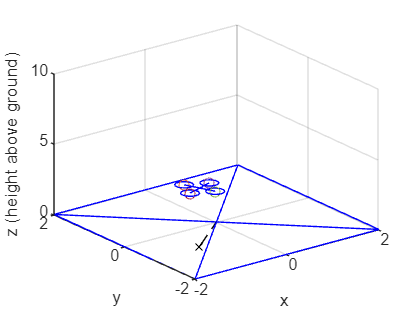

sl_quadrotor;
mdl_quadrotor;
sim('sl_quadrotor');

about result

result [double] : 2407x16 (308.1 kB)


## Creating data sets with error from simulated drone flight

% Extracting time-vector, XYZ-positions-matrix and RPY-orientations-matrix
% from results of simulation
timeSteps = linspace(0,1,length(result));
positionsXYZ = result(:,1:3);
orientationsRPY = result(:,7:9);

% Getting the sizes of position/orientation-matrices
sizeXYZ = size(positionsXYZ)

sizeXYZ =         2407           3


sizeRPY = size(orientationsRPY)

sizeRPY =         2407           3



% Size of error
errorCoefficient = 0.05;       % (random) error is 5% of actual value
orientationsDriftR = timeSteps' .* errorCoefficient .* orientationsRPY(:,1);
orientationsDriftP = timeSteps' .* errorCoefficient .* orientationsRPY(:,2);
orientationsDriftY = timeSteps' .* errorCoefficient .* orientationsRPY(:,3);
orientationsDrift = [orientationsDriftR orientationsDriftP orientationsDriftY];

% Creating matrices with error (using normally-distributed rng)
positionsXYZnoisy = positionsXYZ + errorCoefficient * randn(sizeXYZ);
orientationsRPYnoisy = orientationsRPY + orientationsDrift + errorCoefficient * randn(sizeRPY);

## Filter out error using Extended Kalman Filter

% Initialization
dt = timeSteps(2) - timeSteps(1); % Time step from simulation data
state = [positionsXYZ(1, :)'; zeros(3, 1); orientationsRPY(1, :)']; % Initial state
P = eye(9); % Initial state covariance matrix
Q = 0.01 * eye(9); % Process noise covariance matrix
R = 0.05 * eye(6); % Measurement noise covariance matrix (3 for position, 3 for orientation)

% State transition function F and observation matrix H
F = eye(9); 
F(1:3, 4:6) = dt * eye(3); % Position updates based on velocity

H = [eye(3), zeros(3, 6); zeros(3, 3), eye(3), zeros(3)]; % Observation model

% Initialize arrays to store filtered results
filteredPositions = zeros(size(positionsXYZ));
filteredOrientations = zeros(size(orientationsRPY));

% EKF loop
for t = 1:length(timeSteps)
    % Prediction step
    state_pred = F * state; % State prediction
    P_pred = F * P * F' + Q; % Predicted covariance

    % Measurement update
    measurement = [positionsXYZnoisy(t, :)'; orientationsRPYnoisy(t, :)'];
    y = measurement - H * state_pred; % Innovation (measurement residual)
    S = H * P_pred * H' + R; % Innovation covariance
    K = P_pred * H' / S; % Kalman gain
    state = state_pred + K * y; % Updated state estimate
    P = (eye(9) - K * H) * P_pred; % Updated covariance estimate

    % Store filtered results
    filteredPositions(t, :) = state(1:3)';
    filteredOrientations(t, :) = state(7:9)';
end


## Plots

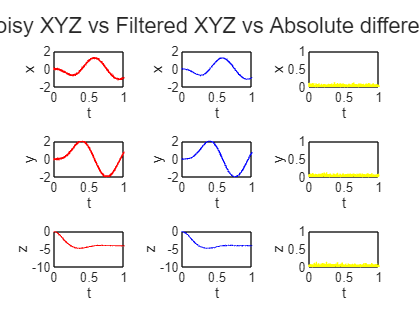

% Comparison of noisy vs filtered

% XYZ

figure('Name', "Noisy XYZ vs Filtered XYZ vs Absolute difference")
tile1 = tiledlayout(3,3);
title(tile1, "Noisy XYZ vs Filtered XYZ vs Absolute difference")

% noisy X-positions
nexttile
plot(timeSteps, positionsXYZnoisy(:,1), 'r')
axis([0 1 -2 2])
xlabel('t');
ylabel('x');

% filtered X-positions
nexttile
plot(timeSteps, filteredPositions(:,1), 'b')
axis([0 1 -2 2])
xlabel('t');
ylabel('x');

% DeltaNoisyFiltered X
nexttile
plot(timeSteps, abs(positionsXYZnoisy(:,1) - filteredPositions(:,1)), 'y')
axis([0 1 0 1])
xlabel('t');
ylabel('x');

% noisy Y-positions
nexttile
plot(timeSteps, positionsXYZnoisy(:,2), 'r')
axis([0 1 -2 2])
xlabel('t');
ylabel('y');

% filtered Y-positions
nexttile
plot(timeSteps, filteredPositions(:,2), 'b')
axis([0 1 -2 2])
xlabel('t');
ylabel('y');

% DeltaNoisyFiltered Y
nexttile
plot(timeSteps, abs(positionsXYZnoisy(:,2) - filteredPositions(:,2)), 'y')
axis([0 1 0 1])
xlabel('t');
ylabel('y');

% noisy Z-positions
nexttile
plot(timeSteps, positionsXYZnoisy(:,3), 'r')
axis([0 1 -10 0])
xlabel('t');
ylabel('z');

% filtered Z-positions
nexttile
plot(timeSteps, filteredPositions(:,3), 'b')
axis([0 1 -10 0])
xlabel('t');
ylabel('z');

% DeltaNoisyFiltered Z
nexttile
plot(timeSteps, abs(positionsXYZnoisy(:,3) - filteredPositions(:,3)), 'y')
axis([0 1 0 1])
xlabel('t');
ylabel('z');

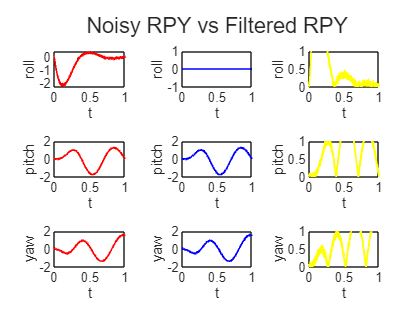


% RPY

figure('Name', "Noisy RPY vs Filtered RPY")
tile1 = tiledlayout(3,3);
title(tile1, "Noisy RPY vs Filtered RPY")

% noisy Roll
nexttile
plot(timeSteps, orientationsRPYnoisy(:,3), 'r')
xlabel('t');
ylabel('roll');

% filtered Roll
nexttile
plot(timeSteps, filteredOrientations(:,3), 'b')
xlabel('t');
ylabel('roll');

% Roll difference
nexttile
plot(timeSteps, abs(orientationsRPYnoisy(:,3) - filteredOrientations(:,3)), 'y')
axis([0 1 0 1])
xlabel('t')
ylabel('roll')

% noisy Pitch
nexttile
plot(timeSteps, orientationsRPYnoisy(:,2), 'r')
xlabel('t');
ylabel('pitch');

% filtered Pitch
nexttile
plot(timeSteps, orientationsRPYnoisy(:,2), 'b')
xlabel('t');
ylabel('pitch');

% Pitch difference
nexttile
plot(timeSteps, abs(orientationsRPYnoisy(:,2) - filteredOrientations(:,2)), 'y')
axis([0 1 0 1])
xlabel('t')
ylabel('pitch')

% noisy Yaw
nexttile
plot(timeSteps, orientationsRPYnoisy(:,1), 'r')
xlabel('t');
ylabel('yaw');

% filtered Yaw
nexttile
plot(timeSteps, orientationsRPYnoisy(:,1), 'b')
xlabel('t');
ylabel('yaw');

% Roll difference
nexttile
plot(timeSteps, abs(orientationsRPYnoisy(:,1) - filteredOrientations(:,1)), 'y')
axis([0 1 0 1])
xlabel('t')
ylabel('yaw')


%plot(timeSteps, positionsXYZnoisy(:,1), 'r', timeSteps, filteredPositions(:,1), 'b');
%legend('Noisy Position X', 'Filtered Position X');
% xlabel('Time (s)');
% ylabel('Position (m)');
%title('EKF Position Filtering');
